# Transformacja Karhunena-Loevego i analiza składowych głównych w zastosowaniu do kompresji obrazów

dr hab. inż. Grzegorz Stępniak

Celem laboratorium jest przedstawienie dwóch metod kompresji obrazów oraz jednej metody pozwalającej na wykrywanie twarzy w zdjęciach.

Zanim jednak przejdziemy do wykonywania ćwiczenia, warto przedstawić i omówić metodę rozkładu dowolnych macierzy na trzy składowe. Metoda rozkładu według wartości osobliwych (SVD – ang. singular value decomposition) może być wykorzystana do redukcji wymiaru macierzy.  

Dana jest macierz $\mathit{\mathbf{X}}$ o wymiarach $\mathit{\mathbf{m}}\times \mathit{\mathbf{n}}$ i współczynnikach rzeczywistych lub zespolonych. Macierz ta może być zapisana jako iloczyn macierzy  

$\mathit{\mathbf{X}}=\mathit{\mathbf{U}}\Sigma {\mathit{\mathbf{V}}}^{*\;}$ (gwiazdka oznacza sprzężenie hermitowskie).

gdzie $\mathit{\mathbf{U}}$ i $\mathit{\mathbf{V}}$ są macierzami unitarnymi tj. ${\textrm{UU}}^* ={\textrm{VV}}^* ={\mathit{\mathbf{U}}}^* \mathit{\mathbf{U}}={\mathit{\mathbf{V}}}^* \mathit{\mathbf{V}}=\mathit{\mathbf{I}}$, a $\Sigma$ jest macierzą diagonalną o dodatnich wartościach na przekątnej. W przypadku kiedy macierz $\mathit{\mathbf{X}}$ jest macierzą rzeczywistą, macierze $\mathit{\mathbf{U}}$ i $\mathit{\mathbf{V}}$ są macierzami ortogonalnymi tj. ${\textrm{UU}}^{\mathit{\mathbf{T}}} ={\textrm{VV}}^{\mathit{\mathbf{T}}} =\mathit{\mathbf{I}}$ . Wymiar macierzy $\mathit{\mathbf{U}}$ to $\mathit{\mathbf{m}}\times \mathit{\mathbf{m}}$, macierzy $\Sigma \;$ to $\mathit{\mathbf{m}}\times \mathit{\mathbf{n}}$, a macierzy $\mathit{\mathbf{V}}$ to $\mathit{\mathbf{n}}\times \mathit{\mathbf{n}}$. Wymiary macierzy przedstawiono graficznie na Rys. 1. Wartości położone na przekątnej $\sigma_{\mathit{\mathbf{i}}} =\Sigma {\;}_{\mathit{\mathbf{i}},\mathit{\mathbf{i}}}$ macierzy nazywamy wartościami osobliwymi (ang. singular values). Macierze $\mathit{\mathbf{U}},\mathit{\mathbf{V}}$ to z kolei macierze lewych i prawych wektorów osobliwych. Z uwagi na to, że rząd macierzy $\mathit{\mathbf{X}}$ wynosi $\mathit{\mathbf{r}}\le \min \left(\mathit{\mathbf{m}},\mathit{\mathbf{n}}\right)$, liczba niezerowych wartości osobliwych wynosi co najwyżej $\mathit{\mathbf{r}}$. Stąd wynika kompaktowy rozkład SVD na macierze $\mathit{\mathbf{U}}$ o wymiarze $\mathit{\mathbf{m}}\times \mathit{\mathbf{r}}$, macierz $\Sigma \;$ to $\mathit{\mathbf{r}}\times \mathit{\mathbf{r}}$, i macierz $\mathit{\mathbf{V}}$ $\mathit{\mathbf{n}}\times \mathit{\mathbf{r}}$(Rys. 1)

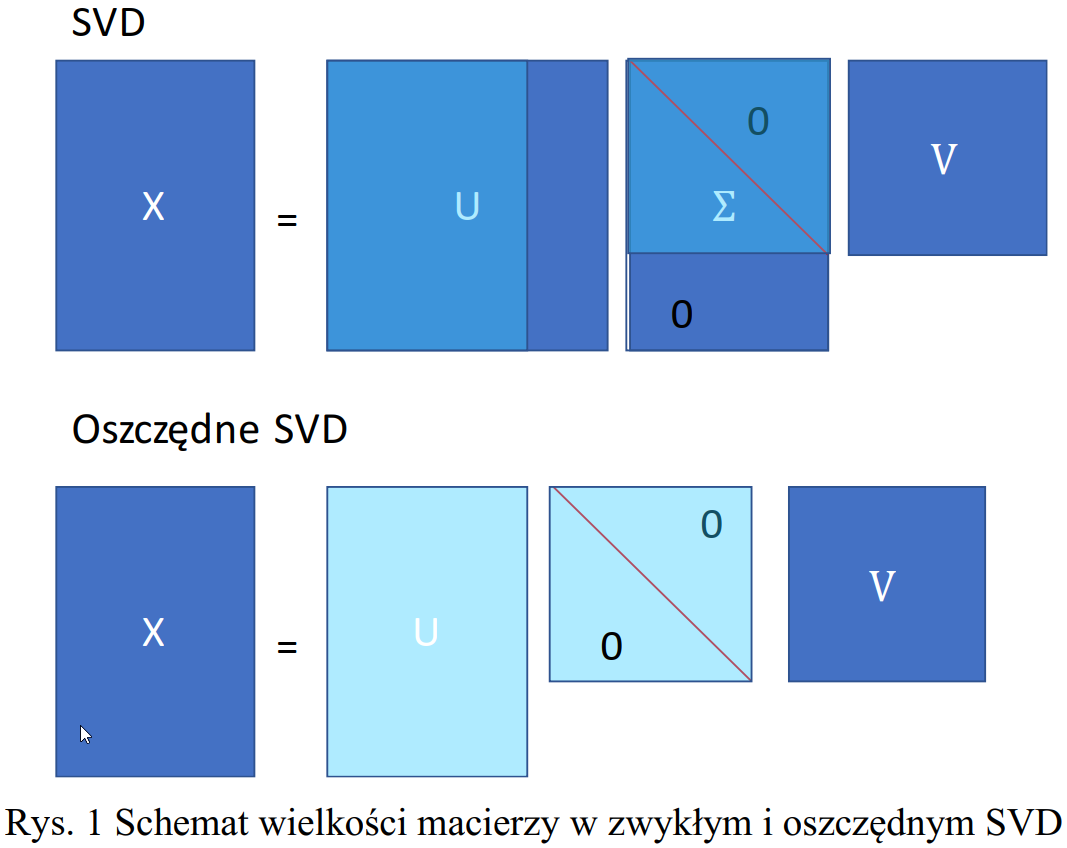

Rozkład SVD możemy wykorzystać do kompresji zdjęć. Zauważmy, że (dla uproszczenia) w przypadku zdjęć kwadratowych i czarno-białych, wymagana pamięć do jego zapisania w ogólności jest równa iloczynowi $M*M$. Dla zdjęcia o wymiarach 512 na 512 pikseli będzie to dokładnie 262144 pikseli. Jeżeli jeden piksel zapisany jest za pomocą jednego bajta, takie zdjęcie będzie zajmowało ponad 260 kB.

Ważną cechą rozkładu SVD jest to, że pierwsze kolumny macierzy $U,V$ i początkowe elementy diagonali macierzy $\Sigma$ zawierają najwięcej istotnych informacji na temat przetwarzanego obrazu. Możemy więc, dzięki temu, zmniejszyć rozmiary zapisywanego zdjęcia poprzez redukcję rzedów tychże macierzy. Dla przykładu, załóżmy, że do zapisania zdjęcia bierzemy wyłącznie rząd $r$. Wówczas, wystarczy, że zachowamy informacje wyłącznie o $M*r+r+M*r$ pikselach. Dla $r=10,M=512$, zdjęcie zajmować będzie $5120+10+5120=5130$ bajtów.

Dla zdjęć kwadratowych redukcja rozmiaru z rzędem $r$ równa jest $\frac{2*M*r+r}{M^2 }=\frac{r*\left(2*M+1\right)\;}{M^2 }\approx \frac{2*r}{M}$. Kompresja ma sens tylko wtedy, gdy $r\le \frac{M^2 }{2*M+1}\approx \frac{M}{2}$. Dla wyższych r bardziej "opłaca" się zapisać oryginał.

Dla obrazków niekwadratowych:

Ciekawy przykład SVD: [https://timbaumann.info/svd-image-compression-demo/](https://timbaumann.info/svd-image-compression-demo/)

## UWAGI

- Wykonuj zadania po kolei, gdyż zmienne w następnych krokach zależą od poprzednich.

# Rozkład SVD

W pierwszym kroku wczytujemy zdjęcie. Każde zdjęcie jest macierzą o wymiarach $\mathit{\mathbf{m}}\times \mathit{\mathbf{n}}\times \mathit{\mathbf{c}}$ (dla kwadratowych np. $\mathit{\mathbf{m}}\times \mathit{\mathbf{m}}\times \mathit{\mathbf{c}}$), gdzie $\mathit{\mathbf{m}}\times \mathit{\mathbf{n}}$ to rozmiary w pikselach, a $\mathit{\mathbf{c}}$ oznacza liczbę kanałów kolorowych (dla cz.-b. $\mathit{\mathbf{c}}=1$, a dla RGB $\mathit{\mathbf{c}}=3$).

%A=imread('./yalefaces/subject01.glasses');
A=imread('./otherpictures/motyl.tif');
%A=imread('./otherpictures/Mandrill.bmp');
%A=imread('./otherpictures/wmn.bmp');
disp(['Wymiary zdjęcia: ' num2str(size(A))])

Musimy się upewnić, że zdjęcie będzie czarno-białe:

X=double(im2gray(A));

Wyświetlmy wczytane zdjęcie:

figure('Color','w');
imagesc(X)
title('Wczytane zdjęcie')
colormap gray

Rozbijamy zdjęcie (macierz X) na trzy macierze: USV. Pamiętamy, że rozkład SVD umożliwia zapisanie macierzy X jako iloczyn:


$$X=U\cdot S\cdot V^*$$


Pamiętaj też, że macierz $S$ jest diagonalna.

[Nh,Nw]=size(X);
[U,S,V]=svd(X);

## ZADANIA DO WYKONANIA #0

- *Obejrzyj i skomentuj obrazy w zależności od wymiaru aproksmacji SVD*

- *Obejrzyj i skomentuj wygląd kilku wybranych elementów bazy - najlepiej pierwsze i ostatnie elementy.*

*Do powyższych dwóch zadań skorzystaj z poniższych sekcji.*

Sprawdźmy więc, jak wygląda aproksymacja zdjęcia dla rzędu mniejszego niż maksymalny możliwy (uwaga! maksymalny możliwy rząd macierzy równy jest $\min \left(N,M\right)$.

r_svd_approx=60;
wymiary_po_kompresji = 2*Nh*r_svd_approx+r_svd_approx;

%aproksymacja zdjęcia to odpowiedni iloczyn macierzy U,S,V. Bierzemy
%pierwsze r kolumn U i V, oraz pierwsze r kolumn i wierszy macierzy S.
Xappx=U(:,1:r_svd_approx)*S(1:r_svd_approx,1:r_svd_approx)*V(:,1:r_svd_approx)';

compression_ratio_svd = (1-wymiary_po_kompresji/(Nh*Nh))*100

Sprawdźmy jak wygląda zdjęcie przed i po aproksymacji.

figure('Color','w');
subplot(1,2,1)
imagesc(Xappx);
colormap gray
axis off
title(['Aproksymacja r=' num2str(r_svd_approx)])
subplot(1,2,2);
imagesc(X);
colormap gray
axis off
title('Oryginał')

Błąd aproksymacji obliczać będziemy średniokwadratowo.

err_svd=sum(sum((Xappx-X).^2))/sum(sum(X.^2))

Bazą przekształcenia jest iloczyn macierzy ${\textrm{UV}}^*$. Możemy teraz sprawdzić jak wygląda baza naszego przekształcenia. R-ty element bazy stanowi iloczyn $U\left(:,R\right)\cdot {V\left(:,R\right)}^{\prime }$.

R=300;
UV=U(:,R)*V(:,R)';
figure('Color','w')
imagesc(UV);
colormap gray
axis off
title([num2str(R) '# element bazy SVD'])

## ZADANIA DO WYKONANIA #1

- *Obejrzyj i skomentuj obrazy w zależności od wymiaru aproksmacji SVD*

- *Obejrzyj i skomentuj wygląd kilku wybranych elementów bazy - najlepiej pierwsze i ostatnie elementy.*

- *Zbadaj błąd aproksymacji wybranych obrazków w funkcji rzędu. Posłuż się poniższym kodem - odkomentuj i uzupełnij.*

% A_zad=imread('./otherpictures/Mandrill.bmp');
% X_zad=double(im2gray(A_zad));
% [U_zad,S_zad,V_zad]=svd(X_zad);
% 
% R_max = min(size(A_zad,[1 2]));
% 
% errs_svd = [];
% for r=1:R_max
% 
%     Xappx_zad = %%%% UZUPELNIJ WZOREM NA APROKSYMACJE ZDJECIA Z WYKORZYSTANIEM SVD
% 
%     errs_svd(r) = %%%%%% UZUPELNIJ WZOREM NA BLAD SREDNIOKWADRATOWY
% end
% 
% figure('color','w')
% plot(1:R_max,log10(errs_svd));
% xlim([1 R_max]);
% ylim([-9 -1])
% hold on;
% plot(numel(X_zad)/(1+sum(size(X_zad)))*ones(1,2), ylim,'-','Color',[1 0 0])
% xlabel('Rząd aproksymacji');
% ylabel('Błąd aproksymacji (log10)');
% legend({'Błąd SVD','Kiedy sie oplaca kompresja'},'NumColumns',2,'Location','best');

# Transformata DCT

Zapewne kojarzymy transformatę Fouriera, która umożliwia w ogólności przejście z dziedziny czasu do dziedziny częstotliwości (a w zasadzie zapisanie sygnału w formie sumy [lub całki] sygnałów harmonicznych typu exp). Istnieje również transformata cosinusowa, gdzie bazą nie są funkcje zespolone, a wyłącznie funkcje typu cosinus.

Podobną operację można zrealizować w zdjęciach tj. zapisać obraz jako skończoną sumę dwuwymiarowych, ortogonalnych względem siebie, funkcji cosinus.

W pierwszym kroku wczytajmy zdjęcie. Warto użyć tego samego co na początku laboratorium :)

A=imread('./otherpictures/motyl.tif');
%A=imread('./otherpictures/wmn.bmp');
X=double(im2gray(A));
[Nh,Nw]=size(X);

Do policzenia transformaty DCT wykorzystamy wbudowaną funkcję DCT w MATLABie:

X_dct = dct2(X);

Wyświetlmy widmo amplitudowe obrazka w skali logarytmicznej:

figure('color','w');
surf(1:size(A,2),1:size(A,1),log10(abs(X_dct)),'EdgeColor','none');
xlim([1 size(A,2)])
ylim([1 size(A,1)])
colorbar
colormap jet
ylabel('Wiersze')
xlabel('Kolumny')
view([0 90])
box on

## ZADANIA DO WYKONANIA #2

- Skomentuj wygląd widma amplitudowego transformaty DCT. Pamiętaj, że analizujemy go w skali logarytmicznej. Gdzie znajduje się najwięcej energii obrazka? Co w transformacie DCT oznacza numer kolumny i wiersza?

Podobnie jak rozkład SVD, tak i transformatę DCT można wykorzystać do kompresji obrazków. Kompresję obrazów z wykorzystaniem DCT realizujemy w formie usunięcia tych składowych cosinusowych, które mają najmniejszy wkład w reprezentację sygnału.

Składowe najbardziej znaczące to te o największej wartości co do modułu. Posortujmy je więc przechodząc ówcześnie z dziedziny dwu do jednowymiarowej.

X_dct_linear=X_dct(:);
[ Avec, Ind ] = sort(abs(X_dct_linear),1,'ascend');

Aproksymacja obrazka rzędu $r$ z wykorzystaniem transformaty DCT oznacza wybór pierwszych $r^2$ elementów najbardziej znaczących z transformaty. Redukcja rozmiaru z rzędem $r$ równa jest $\frac{r^2 }{M^2 }$.

r_dct_approx = 60;
compression_ratio_dct = (1-r_dct_approx^2/numel(X_dct))*100
[ ind_row, ind_col ] = ind2sub(size(X_dct),Ind(1:Nh*Nw-r_dct_approx^2));%wybieramy pierwsze r_dct_approx^2 elementów, czyli inaczej: usuwamy M^2-r_dct_approx^2 elementy

X_dct_appx=X_dct;
for k=1:length(ind_row) %zwroc uwage, ze length(ind_row) = M^2-r_dct_approx^2
    X_dct_appx(ind_row(k),ind_col(k))=0; %ustawiamy zera tam dla skladowych najmniej znaczacych
end
Xappx_dct = idct2(X_dct_appx);

figure('Color','w')
subplot(1,2,1)
imagesc(Xappx_dct);
colormap gray
axis off
title(['Aproksymacja r=' num2str(round(sqrt(r_dct_approx^2)))])
subplot(1,2,2);
imagesc(X);
colormap gray
axis off
title('Oryginał')

Policzmy błąd średniokwadratowy:

err_dct=sum(sum((Xappx_dct-X).^2))/sum(sum(X.^2)) 

Podobnie jak w SVD, dla DCT możemy wyświetlić bazę.

%% wizualizacja bazy
% R1,R2 - indeksy bazy
R1=13;
R2=4;

UV=zeros(Nh,Nw);
UV(R1,R2)=1;
figure('Color','w')
imagesc(idct2(UV));
colormap gray
axis off
title(['(' num2str(R1) ',' num2str(R2) ')# element bazy DCT'])


## ZADANIA DO WYKONANIA #3

- *Obejrzyj i skomentuj obrazy w zależności od wymiaru aproksmacji DCT*

- *Obejrzyj i skomentuj wygląd kilku wybranych elementów bazy - najlepiej pierwsze i ostatnie elementy.*

- *Zbadaj błąd aproksymacji wybranych obrazków w funkcji rzędu. Posłuż się poniższym kodem - odkomentuj i uzupełnij. Porównaj z SVD.*

% A_zad=imread('./otherpictures/Mandrill.bmp');
% X_zad=double(im2gray(A_zad));
% [Nh,Nw]=size(X_zad);
% X_dct_zad = dct2(X_zad);  %ORYGINAL
% X_dct_zad_linear=X_dct_zad(:);
% [ Avec_zad, Ind_zad ] = sort(abs(X_dct_zad_linear),1,'ascend');
% 
% 
% R_max = min(size(A_zad,[1 2]));
% 
% errs_dct = [];
% for r=1:R_max
% 
%     [ ind_row, ind_col ] = ind2sub(size(X_dct_zad),Ind_zad(1:Nh*Nw-r^2));
% 
%     X_dct_appx_zad=X_dct_zad;
%     for k=1:length(ind_row)
%         X_dct_appx_zad(ind_row(k),ind_col(k))=0;
%     end
%     Xappx_zad = idct2(X_dct_appx_zad);  %APROKSYMACJA
% 
%     errs_dct(r) = %%%%%% UZUPELNIJ WZOREM NA BLAD SREDNIOKWADRATOWY
% end
% 
% figure('color','w')
% plot(1:R_max,log10(errs_dct));
% xlim([1 R_max]);
% ylim([-9 -1])
% hold on;
% plot(R_max/2*ones(1,2), ylim,'-','Color',[1 0 0])
% xlabel('Rząd aproksymacji');
% ylabel('Błąd aproksymacji (log10)');
% legend({'Błąd DCT'},'NumColumns',2,'Location','best');

## ZADANIA DO WYKONANIA #4

- *Przeanalizuj wykres skumulowanej energii współczynników rozwinięcia od rzędu aproksymacji. Co to oznacza dla aproksymacji i porównania błędów DCT z SVD?*

figure('color','w');
sigm=cumsum(diag(S));
plot((sigm/sum(diag(S))))

hold on;
e_dct = cumsum(flipud(Avec))/sum(Avec);
x_Avec = 1:floor(sqrt(length(Avec)));
plot(x_Avec,e_dct((x_Avec).^2))

plot(xlim,.9*ones(1,2))

xlim([1 max(x_Avec)])
ylim([0 1])
xlabel('Rząd przybliżenia')
ylabel('Skumulowana energia')
legend({'SVD','DCT','90%'},'Box','off','Location','best')

# Metoda składowych głównych (PCA)  

Metoda analizy głównych składowych (ang. PCA – principal component analysis) pozwala na znalezienie zbioru wzajemnie ortogonalnych wektorów najlepiej odwzorowujących zbiór danych. W analizie sygnałów metoda ta znana jest jako twierdzenie Karhunena – Loevego. Twierdzenie to mówi, że proces stochastyczny o zerowej wartości średniej może być reprezentowany jako liniowa kombinacja funkcji ortogonalnych na przedziale czasu, w podobny sposób jak funkcja deterministyczna może być reprezentowana jako liniowa kombinacja zespolonych funkcji harmonicznych w transformacie Fouriera. Co więcej, twierdzenie Karhunena Loevego podaje jak wyznaczyć te funkcje ortogonalne dla danego procesu: wyznacza się je jako wektory własne macierzy autokowariancji procesu. Co więcej, podobnie jak w rozkładzie na wartości własne, ma miejsce własność koncentracji energii w funkcjach niższego rzędu.

## Zbiór twarzy

W pierwszym kroku wczytujemy zdjęcia twarzy.

list=ls('./yalefaces/');
for ni=1:size(list,1)-2
    yalefaces(:,:,ni)=imread(strcat('./yalefaces/',list(ni+2,:)));
end

Możemy wyświetlić kilka twarzy z wczytanego zbioru.

figure('color','w');
for i=1:4
    subplot(2,2,i);
    imagesc(yalefaces(:,:,11*i-1));
    colormap gray
    axis off
    title(['Twarz nr ' num2str(11*i-1)])
end

## Tworzenie zbioru twarzy własnych

W pełnym zbiorze znajduje się 165 twarzy. Stwórzmy zbiór twarzy własnych z np. 140 twarzy tak, aby część z nich było poza zbiorem twarzy własnych.

TRAIN=140; %ilość twarzy w zbiorze treningowym
[h, w, n] = size(yalefaces);
d = h * w;
x = reshape(yalefaces, [d n]);
x_all = double(x); %wszystkie twarze
x_train = double(x(:,1:TRAIN)); %twarze wykorzystane do zbioru tw. wlasnych

W pierwszym kroku należy obliczyć "średnią" twarz, którą później odejmiemy od zbioru treningowego. Chodzi o to, abyśmy przetwarzali zbiór, z którego pozbyliśmy się średniej wartości.

% srednia twarz
meanmatrix = mean(x_train, 2);

Sprawdźmy, jak wygląda średnia twarz ze zbioru

figure('color','w');
imagesc(reshape(meanmatrix,h,w));
colormap gray; axis off;
title('Średnia twarz')

Zgodnie z kolejnym krokiem, od zbioru twarzy trenujących odejmujemy średnią twarz:

X_train=x_train-meanmatrix*ones(1,TRAIN);
X_all=x_all-meanmatrix*ones(1,size(yalefaces,3));

Sprawdźmy jak wyglądają wcześniej wyświetlone cztery twarze po odjęciu średniej. To co obserwujemy to swoista odchyłka od twarzy średniej.

figure('color','w');
for i=1:4
    subplot(2,2,i);
    imagesc(reshape(X_all(:,11*i-1),h,w));
    colormap gray
    axis off
    title(['Twarz nr ' num2str(11*i-1)])
end

W celu zbudowania bazy twarzy własnych korzystamy z rozkładu SVD. Rozkładowi podlegać będzie wektor twarzy $X_{\textrm{train}}$.

[U_eigfac,S_eigfac,V_eigfac]=svd(X_train,'econ');
sig_eigfac=diag(S_eigfac);

Pamiętaj, że wartości na diagonali $S_{\textrm{eigfac}}$ określają "istotność" poszczególnych elementów bazy w zbiorze twarzy własnych.

Sprawdźmy więc jak wyglądają współczzynniki na diagonali macierzy S.

figure('color','w')
subplot(1,2,1)
plot(log10(diag(S_eigfac))) %wartosci na diagonali
xlim([1 TRAIN])
ylabel('Współczynnik twarzy własnej (log10)')
xlabel('Numer elementu diagonali')
title('Diag')

subplot(1,2,2)
plot(cumsum(sig_eigfac)) %skumulowana suma na diagonali
xlim([1 TRAIN])
ylabel('Skumulowana suma wartości na diagonali')
xlabel('Liczba twarzy własnych')
title('Cumsum diag')

Wyświetlmy teraz kilka twarzy własnych ze zbioru.

NrEigenface=40;
figure('color','w')
tiledlayout('TileSpacing','none')
for i=1:NrEigenface
    nexttile
    imagesc(reshape(U_eigfac(:,i),h,w)) %plot eigenface
    colormap gray; axis off;
end
sgtitle('Wybrane twarze własne')

## ZADANIA DO WYKONANIA #5

- Obejrzeć i skomentować obliczone twarze własne.

- Które twarze własne mają największy wkład w reprezentację całego zbioru a które najmniejszy? <-- posłuż się tutaj analizą wartości na diagonali

## `Aproksymacja twarzy z wykorzystaniem zbioru twarzy własnych`

Podobnnie jak w przypadku rozkładu SVD, zbiór twarzy własnych można wykorzystać do kompresji zdjęć twarzy i ich aproksymacji. Rząd aproksymacji w przypadku PCA ma taki sam sens jak w przypadku rozkładu SVD. Sprawdźmy jak wyglądają twarze z i spoza zbioru.

Wybierzmy numery twarzy z i spoza zbioru. Numer spoza zbioru będzie większy lub równy parametrowi TRAIN.

nr_out=150; %wybrana twarz spoza zbioru yalefaces
nr_in=50; %wybrana twarz spoza zbioru yalefaces

Rząd aproksymacji oznacza ile bierzemy zdjęć ze zbioru twarzy własnych.

r_face1=100; %liczba wyrazow aproksymacji

W celu aproksymacji twarzy z wykorzystaniem zbioru należy wykonać rzut twarzy na przestrzeń twarzy własnych i następnie dodać średnią twarz.

%aproksymacja spoza zbioru
x_coord_out=U_eigfac(:,1:r_face1)'*X_all(:,nr_out);
X_face_appx_out=meanmatrix+(U_eigfac(:,1:r_face1)*x_coord_out);
%aproksymacja ze zbioru
x_coord_in=U_eigfac(:,1:r_face1)'*X_all(:,nr_in);
X_face_appx_in=meanmatrix+(U_eigfac(:,1:r_face1)*x_coord_in);

Błąd aproksymacji liczymy tak samo jak w poprzednich zadaniach.

err_out=sum((X_face_appx_out-meanmatrix-X_all(:,nr_out)).^2)/sum((X_all(:,nr_out)).^2)
err_in=sum((X_face_appx_in-meanmatrix-X_all(:,nr_in)).^2)/sum((X_all(:,nr_in)).^2)

Sprawdźmy jak wyglądają zaproksymowane twarze.

figure('color','w');
subplot(2,2,1);
imagesc(reshape(X_face_appx_out,h,w));colormap gray;axis off
title('Spoza aproks.')
subplot(2,2,2);
imagesc(reshape(x_all(:,nr_out),h,w));colormap gray;axis off
title('Spoza oryg.')
subplot(2,2,3);
imagesc(reshape(X_face_appx_in,h,w));colormap gray;axis off
title('Ze aproks.')
subplot(2,2,4);
imagesc(reshape(x_all(:,nr_in),h,w));colormap gray;axis off
title('Ze oryg.')

## ZADANIA DO WYKONANIA #6

- Na podstawie empirycznych obserwacji określ jak wiele twarzy własnych potrzeba aby rozpoznać twarz/gest na zdjęciu ze zbioru. wykorzystaj do tego powyższy kod.gu

- Przy pomocy poniższego kodu przeanalizuj jak zachowuje się błąd aproksymacji w funkcji rzędu aproksymacji dla twarzy ze i spoza zbioru. Spróbuj skorelować błąd z wartościami na diagonali S.

% R_max = TRAIN;
% 
% errs_in = [];
% errs_out = [];
% for r=1:R_max
%     x_coord_out=U_eigfac(:,1:r)'*X_all(:,nr_out);
%     X_face_appx_out=meanmatrix+(U_eigfac(:,1:r)*x_coord_out);
% 
%     x_coord_in=U_eigfac(:,1:r)'*X_all(:,nr_in);
%     X_face_appx_in=meanmatrix+(U_eigfac(:,1:r)*x_coord_in);
% 
%     %%%%%% UZUPELNIJ WZORY NA BLAD SREDNIOKWADRATOWY
%     errs_out(r)=%%%%% 
%     errs_in(r)=%%%%%% 
% end
% 
% figure('color','w')
% plot(1:R_max,log10(errs_out));
% hold on;
% plot(1:R_max,log10(errs_in));
% xlim([1 R_max]);
% ylim([-5 0])
% xlabel('Rząd aproksymacji');
% ylabel('Błąd aproksymacji (log10)');
% legend({'Błąd SPOZA','Błąd ZE'},'NumColumns',2,'Location','best');

## ZADANIA DO WYKONANIA #7

- Skorzystaj z poniższego kodu. Zbadaj jak zależy aproksymacja twarzy ze zbioru/spoza zbioru w zależności od objętości zbioru trenującego (parametr TRAIN). Możesz wykorzystać do tego błąd aproksymacji (err).

TRAIN_MAX = 140;

face_in_set = 1; %NIECH ZOSTANIE 1
face_out_set = 160; % wybierz z zakresu <TRAIN_MAX+1, 165>
x_out = x_all(:,face_out_set);

it = 1;
err_in_train = [];err_out_train = [];
for TR=1:TRAIN_MAX
    r = TR;
    % vectorize images
    x1_tr = x_all(:,1:TR);
    % subtract mean
    meanmatrix = mean(x1_tr, 2);

    X1_tr=x1_tr-meanmatrix*ones(1,TR);
    XO_tr=x_out-meanmatrix*ones(1,TR);
    [U_tr,S_tr,V_tr]=svd(X1_tr,'econ');

    %%FACE IN THE SET
    x_coord=U_tr(:,1:r)'*X1_tr(:,face_in_set);
    rf=meanmatrix+(U_tr(:,1:r)*x_coord);
    err_in_train(it)=sum((rf-meanmatrix-X1_tr(:,face_in_set)).^2)/sum((X1_tr(:,face_in_set)).^2);

    %%FACE OUT OF A SET
    x_coord=U_tr(:,1:r)'*XO_tr;
    rf=meanmatrix+(U_tr(:,1:r)*x_coord);
    err_out_train(it)=sum((rf-meanmatrix-XO_tr).^2)/sum((XO_tr).^2);
    it = it +1;
end
%%
figure('color','w');
plot(log10(err_in_train(1:it-1)),'LineWidth',3)
hold on;
plot(log10(err_out_train(1:it-1)),'LineWidth',3)
xlabel('Training length')
ylabel('log10(Error)')
legend({'In','Out'})
ylim([-30 1])

## Wykrywanie twarzy

Zbiór twarzy własnych można wykorzystać do wykrywania osób na zdjęciach. Odbywa się to poprzez rzut zdjęcia na przestrzeń twarzy własnych, dzięki któremu można określić odległośc wybranego zdjęcia od przestrzeni twarzy własnych.

W pierwszym kroku do analizy wykorzystania PCA do wykrywania twarzy wykorzystamy pełny zbiór treningowy.

meanmatrix_all = mean(x_all, 2);
X_all=x_all-meanmatrix_all*ones(1,size(yalefaces,3));
[U,S,V]=svd(X_all,'econ');

Wykonajmy rzut wszystkich twarzy ze zbioru na przestrzeń twarzy własnych

%% rzuty na wektory tw. wlasnych
d_s = [];
for nr=1:size(yalefaces,3)
    wybrane_zdjecie = double(x_all(:,nr));
    wybrane_zdjecie_bez_sredniej=reshape(wybrane_zdjecie,[d 1])-meanmatrix_all;
    d_s(:,nr)=U'*wybrane_zdjecie_bez_sredniej;
end

## ZADANIA DO WYKONANIA #8

- Wykorzystując poniższy kod spróbuj dojść do konkluzji czy metoda twarzy własnych jest dobra w wykrywaniu min/tych samych twarzy w zbiorze twarzy ze zdjęciami.

Wybierzmy teraz jakieś zdjęcie ze zbioru i porównajmy jego odległość od przestrzeni twarzy własnych względem odległości innych twarzy. Im mniejsza różnica odległości, tym zdjęcie jest bardziej podobne do wybranego

wybrany=110;

%numery zdjec z ta sama mina
miny_x = unique([fliplr(wybrany:-11:1) wybrany:11:size(yalefaces,3)]);
%numery zdjec tej samej osoby
twarze_x = floor((wybrany-1)/11)*11+[1:11];
%odleglosc wybranej twarzy od rzutu innych twarzy
d_wybr = sqrt(sum((d_s(:,wybrany)-d_s).^2)); 

figure('color','w');
plot(1:size(yalefaces,3),d_wybr);
hold on
d_wybr_miny = sqrt(sum((d_s(:,wybrany)-d_s(:,miny_x)).^2));
plot(miny_x,d_wybr_miny,'x','Color','red','LineWidth',3);
d_wybr_osoba = sqrt(sum((d_s(:,wybrany)-d_s(:,twarze_x)).^2));
plot(twarze_x,d_wybr_osoba);
xlabel('Numer twarzy')
ylabel('Odleglosc wybranej twarzy od innych twarzy');
legend({'Odleglosci','Te same miny','Ta sama osoba'},'NumColumns',2,'Location','best','Box','off')

## Wykrywanie twarzy na zdjęciu spoza zbioru

Możemy również wykorzystać zbiór twarzy własnych do wykrywania twarzy na zdjęciach pochodzących ze zbioru jak i spoza niego. Zasada wykrywania twarzy wymaga, tak jak w zadaniu wyżej, obliczenia odległości rzutu zdjęcia na zbiór twarzy własnych od oryginału. Jeżeli jest ona niska - oznacza to, że na zdjęciu jest twarz. Jeżeli wysoka - na zdjęciu prawdopodobnie nie ma twarzy.

W celu wykonania ćwiczenia najpierw zbudujmy zbiór twarzy wlasnych z mniejszą liczbą twarzy.

n_wykr = 11*12;
meanmatrix_wykr = mean(x_all(:,1:n_wykr), 2);
X_wykr=x_all(:,1:n_wykr)-meanmatrix_wykr*ones(1,n_wykr);
[U,S,V]=svd(X_wykr,'econ');

Następnie rzućmy na przestrzeń twarzy własnych następujące obrazki:

- Twarz ze zbioru

- Twarz spoza zbioru

- Zdjęcie małpki

- Zdjęcie motyla

Wczytajmy zdjęcie malpy i motyla.

A=imread('./otherpictures/motyl.tif');
A=imresize(A,size(yalefaces,[1 2]));
X_motyl=double(im2gray(A));
x_motyl = reshape(X_motyl, [d 1]);

A=imread('./otherpictures/Mandrill.bmp');
A=imresize(A,size(yalefaces,[1 2]));
X_malpa=double(im2gray(A));
x_malpa = reshape(X_malpa, [d 1]);


Wykonajmy rzut zdjęć na przestrzeń twarzy własnych.

%rzut twarzy ze zbioru
nr = randi([1 n_wykr],1,1);
X_ze = double(x_all(:,nr));
X_ze_bez_sredniej=reshape(X_ze,[d 1])-meanmatrix_wykr;
d_s_1 = U'*X_ze_bez_sredniej;
recon = meanmatrix_wykr+(U*d_s_1);
%d_s_1 = sqrt(sum(d_s_1.^2));
o_s_1 = sqrt(sum((recon-(meanmatrix_wykr+X_ze_bez_sredniej)).^2));
e_s_1 = sum((recon-(meanmatrix_wykr+X_ze_bez_sredniej)).^2) / sum((meanmatrix_wykr+X_ze_bez_sredniej).^2);

%rzut twarzy spoza zbioru
nr_spoza = randi([n_wykr+1 size(yalefaces,3)],1,1);
X_spoza = double(x_all(:,nr_spoza));
X_spoza_bez_sredniej=reshape(X_spoza,[d 1])-meanmatrix_wykr;
d_s_2=U'*X_spoza_bez_sredniej;
recon = meanmatrix_wykr+(U*d_s_2);
%d_s_2 = sqrt(sum(d_s_2.^2));
o_s_2 = sqrt(sum((recon-(meanmatrix_wykr+X_spoza_bez_sredniej)).^2));
e_s_2 = sum((recon-(meanmatrix_wykr+X_spoza_bez_sredniej)).^2) / sum((meanmatrix_wykr+X_spoza_bez_sredniej).^2);

%rzut motyla
X_motyl2=reshape(x_motyl,[d 1])-meanmatrix_wykr;
d_s_3=U'*X_motyl2;
recon = meanmatrix_wykr+(U*d_s_3);
%d_s_3 = sqrt(sum(d_s_3.^2));
o_s_3 = sqrt(sum((recon-(meanmatrix_wykr+X_motyl2)).^2));
e_s_3 = sum((recon-(meanmatrix_wykr+X_motyl2)).^2) / sum((meanmatrix_wykr+X_motyl2).^2);

%rzut malpki
X_malpa2=reshape(x_malpa,[d 1])-meanmatrix_wykr;
d_s_4=U'*X_malpa2;
recon = meanmatrix_wykr+(U*d_s_4);
%d_s_4 = sqrt(sum(d_s_4.^2));
o_s_4 = sqrt(sum((recon-(meanmatrix_wykr+X_malpa2)).^2));
e_s_4 = sum((recon-(meanmatrix_wykr+X_malpa2)).^2) / sum((meanmatrix_wykr+X_malpa2).^2);

Zobaczmy oryginalne zdjęcia i ich rekonstrukcje

figure;
sgtitle('Oryginalne')
subplot(2,2,1)
imagesc(yalefaces(:,:,nr));colormap gray;axis off
subplot(2,2,2)
imagesc(yalefaces(:,:,nr_spoza));colormap gray;axis off
subplot(2,2,3)
imagesc(X_motyl);colormap gray;axis off
subplot(2,2,4)
imagesc(X_malpa);colormap gray;axis off
figure;
sgtitle('Rekonstrukcja')
subplot(2,2,1)
imagesc(reshape(meanmatrix_wykr+(U*d_s_1),h,w));colormap gray;axis off
subplot(2,2,2)
imagesc(reshape(meanmatrix_wykr+(U*d_s_2),h,w));colormap gray;axis off
subplot(2,2,3)
imagesc(reshape(meanmatrix_wykr+(U*d_s_3),h,w));colormap gray;axis off
subplot(2,2,4)
imagesc(reshape(meanmatrix_wykr+(U*d_s_4),h,w));colormap gray;axis off

 Sprawdźmy odlegości zdjęć od przestrzeni twarzy własnych.

disp(['Odległość twarzy ze zbioru: ' num2str(o_s_1)]);
disp(['Odległość twarzy spoza zbioru: ' num2str(o_s_2)]);
disp(['Odległość motyla: ' num2str(o_s_3)]);
disp(['Odległość małpy: ' num2str(o_s_4)]);

 Sprawdźmy błędy rekonstrukcji zdjęć.

disp(['MSE twarzy ze zbioru: ' num2str(e_s_1)]);
disp(['MSE twarzy spoza zbioru: ' num2str(e_s_2)]);
disp(['MSE motyla: ' num2str(e_s_3)]);
disp(['MSE małpy: ' num2str(e_s_4)]);

## ZADANIA DO WYKONANIA #9

- Zastanów się dlaczego niektóre twarze spoza zbioru są dalej od przestrzeni twarzy własnych niż zdjęcie małpy/motyla.

- Jak oceniasz metodę wykrywania twarzy na zdjęciu z wykorzystaniem PCA?

- Jak możnaby polepszyć metodę detekcji twarzy?

# EKSTRA - WYKORZYSTANIE CNN DO WYKRYWANIA TWARZY

UWAGA! Tej części nie trzeba wykonywać i uwzględniać w raporcie. Niemniej zachęcam do zapoznania się z poniższą częścią dot. wykrywania twarzy na zdjęciu z wykorzystaniem autoenkodera i sieci NN.

## Autoenkoder do wykrywania twarzy

CNN_TRAIN = 132;
[h_orig, w_orig, ~] = size(yalefaces);
h = 64; w = 64;

X_train = cell(CNN_TRAIN,1);
for i = 1:CNN_TRAIN
    X_train{i} = awgn(imresize(double(yalefaces(:,:,i))/255, [h, w]),2000,'measured'); %mozna zaszumic zdjecia zmieniajac wartość SNR
end

hiddenSize = 40;
autoenc = trainAutoencoder(X_train, hiddenSize, 'MaxEpochs', 100, ...
    'L2WeightRegularization', 0.004, 'SparsityRegularization', 4, ...
    'EncoderTransferFunction','logsig', 'DecoderTransferFunction','logsig', ...
    'SparsityProportion', 0.15);

test_names = {'Twarz ze zbioru','Twarz spoza zbioru','Motyl','Małpa'};
face_in = imresize(double(yalefaces(:,:,randi(CNN_TRAIN)))/255, [h, w]);
face_out = imresize(double(yalefaces(:,:,CNN_TRAIN+1))/255, [h, w]);
butterfly_img = imresize(double(im2gray(imread('./otherpictures/motyl.tif')))/255, [h, w]);
monkey_img = imresize(double(im2gray(imread('./otherpictures/Mandrill.bmp')))/255, [h, w]);

X_test = {face_in, face_out, butterfly_img, monkey_img};
X_reconstructed = predict(autoenc, X_test);

reconstruction_errors = zeros(4,1);
for i = 1:4
    reconstruction_errors(i) = mean(mean((X_test{i} - X_reconstructed{i}).^2));
end

Sprawdźmy jak wyglądają "twarze własne" autoenkodera

figure;
plotWeights(autoenc);

Zróbmy autokodowanie wybranych zdjęć.

figure('color','w');
for i = 1:4
    subplot(2,4,i);
    imagesc(X_test{i}); colormap gray; axis off;
    title({test_names{i}, ['MSE: ' num2str(reconstruction_errors(i),'%.4f')]});
    subplot(2,4,i+4);
    imagesc(X_reconstructed{i}); colormap gray; axis off;
    title('Rekonstrukcja autoenkoder');
end

## Porównanie PCA z autoenkoderem

r_pca = 132;
X_pca_train = zeros(h*w, CNN_TRAIN);
for i = 1:CNN_TRAIN
    X_pca_train(:,i) = X_train{i}(:);
end
mean_face = mean(X_pca_train,2);
X_pca_centered = X_pca_train - mean_face;
[U_pca,~,~] = svd(X_pca_centered, 'econ');

X_pca_test = zeros(h*w,4);
for i = 1:4
    X_pca_test(:,i) = X_test{i}(:);
end

pca_errors = zeros(4,1);
pca_reconstructed = zeros(h, w, 4);
for i = 1:4
    img_centered = X_pca_test(:,i) - mean_face;
    coeffs = U_pca(:,1:r_pca)' * img_centered;
    img_reconstructed = mean_face + U_pca(:,1:r_pca) * coeffs;
    pca_reconstructed(:,:,i) = reshape(img_reconstructed, [h, w]);
    pca_errors(i) = mean((img_reconstructed - X_pca_test(:,i)).^2);
end

figure('color','w');
for i = 1:4
    subplot(2,4,i);
    imagesc(X_test{i}); colormap gray; axis off;
    title({test_names{i}, ['MSE PCA: ' num2str(pca_errors(i),'%.4f')]});
    subplot(2,4,i+4);
    imagesc(pca_reconstructed(:,:,i)); colormap gray; axis off;
    title('Rekonstrukcja PCA');
end

figure('color','w');
bar([reconstruction_errors, pca_errors]);
set(gca, 'XTickLabel', test_names);
legend('Autoenkoder (MSE)','PCA (MSE)');
title('Błąd rekonstrukcji'); ylabel('MSE'); xtickangle(45);

## Wytrenowanie CNN do klasyfikacji twarzy

loadToCNN;
%% Trening sieci CNN
net = trainnet(dataTrain, labelsTrain, layers, "crossentropy",options);


%% Testowanie sieci
% Test na nowej twarzy z YaleFaces
faceTest = imresize(double(yalefaces(:,:,numFacesTrainYale+20))/255, imgSize(1:2));
predFace = minibatchpredict(net, faceTest);
predFace = scores2label(predFace,categories(labelsTrain))

% Test na obrazie nie zawierającym twarzy (np. peppers)
nonFaceTest = imresize(im2double(im2gray(imread('eight.tif'))), imgSize(1:2));
%predNonFace = classify(net, nonFaceTest);
predNonFace = minibatchpredict(net, nonFaceTest);
predNonFace = scores2label(predNonFace,categories(labelsTrain))

figure('color','w');
subplot(1,2,1); imshow(faceTest); title(string(predFace));
subplot(1,2,2); imshow(nonFaceTest); title(string(predNonFace));

## Wykorzystanie wcześniej wytrenowanej CNN do wykrywania twarzy.

Spróbujmy wykryć twarz człowieka wykorzystując wbudowany w MATLAB Toolbox do sieci neuronowych.

Wczytajmy zdjęcia motyla, małpy i człowieka.

X_motyl=imread('./otherpictures/motyl.tif');
X_malpa=imread('./otherpictures/Mandrill.bmp');
X_twarz=imread('./yalefaces/subject01.glasses');
X_twarz = cat(3, X_twarz, X_twarz, X_twarz);

Stwórzmy instancję wcześniej wytrenowanej sieci.

[netG,classNames] = imagePretrainedNetwork("googlenet");

Przeskalujmy zdjęcia do wymaganych wymiarów sieci.

X_motyl=(imresize(X_motyl,netG.Layers(1).InputSize(1:2)));
X_malpa=(imresize(X_malpa,netG.Layers(1).InputSize(1:2)));
X_twarz=(imresize(X_twarz,netG.Layers(1).InputSize(1:2)));

Dokonajmy klasyfikacji zdjęć.

%% motylek
scores_motyl = predict(netG,single(X_motyl));
[label_motyl,score_motyl] = scores2label(scores_motyl,classNames);
figure
imshow(im2single(X_motyl))
title("Prediction: " + string(label_motyl))

%% malpka
scores_malpa = predict(netG,single(X_malpa));
[label_malpa,score_malpa] = scores2label(scores_malpa,classNames);
figure
imshow(im2single(X_malpa))
title("Prediction: " + string(label_malpa))

%% czlowiek
scores_twarz = predict(netG,single(X_twarz));
[label_twarz,score_twarz] = scores2label(scores_twarz,classNames);
figure
imshow(im2single(X_twarz))
title("Prediction: " + string(label_twarz))

Jaki jest problem z wykrywaniem twarzy?

# ZAKOŃCZENIE LABORATORIUM

Raporty (Word, LateX - wszystkie najlepiej w formacie PDF) proszę wysyłać na adres e-mail: juliusz.bojarczuk@pw.edu.pl

W tytule maila proszę umieścić skrótową nazwę przedmiotu (np. [PSITI]).

Czas na zwrot raportu: 7 dni od dnia wykonywania.

W ocenie liczą się wnioski, obserwacje, uwagi i ewentualne inicjatywy własne.